% Imagens no training set
M = 20;

% Lê e mostra imagens (jpg)
S = [];
figure(1);
for i = 1:M
    str = strcat('instructors/', int2str(i));
    str = strcat(str, '.jpg');
    eval('img = imread(str);');
    img = rgb2gray(img);
    img = imresize(img, [300, 300]);
    
    subplot(ceil(sqrt(M)), ceil(sqrt(M)), i)
    imshow(img)
    if i == 3
        title('Instrutores do Curso', 'fontsize', 14)
    end
    drawnow;
    
    [irow, icol] = size(img);
    
    temp = reshape(img', irow * icol, 1);
    S=[S temp];
end

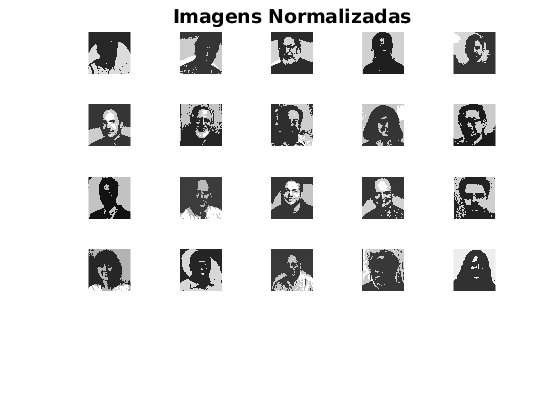

% Normalizar
for i = 1:size(S, 2)
    temp = double(S(:, i));
    m = mean(temp);
    st = std(temp);
    um = 110;
    ustd = 88;
    S(:,i)=(temp-m)*ustd/st+um;
end

figure(2);
for i = 1:M
    str=strcat(int2str(i), '.jpg');
    img = reshape(S(:, i), icol, irow);
    img = img';
    eval('imwrite(img, str)');
    subplot(ceil(sqrt(M)), ceil(sqrt(M)), i)
    imshow(img)
    drawnow;
    if i == 3
        title('Imagens Normalizadas', 'fontsize', 14)
    end
end